The code is a simulation of a control system using a neural network-based approach. It uses a PID controller and a neural network to approximate the dynamics of a nonlinear system.

clc;
clear;
close all;

These lines clear the command window, clear all variables from the workspace, and close all open figure windows.

global beta0 T
beta0 = 0;
T     = 0.01;

These lines define and initialize two global variables `beta0` and `T`. `beta0` is set to 0 and `T` is set to 0.01. `beta0` and `T` are used in the calculation of the beta parameter for updating the PID control gains.

LR = 0.1;       % Learning Rate
x0 = [1;2.5];   % Initial Condition
Tf = 100;
t  = 0:T:Tf;
N = Tf/T;

These lines define and initialize various parameters:

- `LR` is the learning rate used in the weight updates of the neural network and PID control gains.

- `x0` is a 2x1 vector representing the initial condition of the dynamic system.

- `Tf` is the final simulation time.

- `t` is a vector representing time steps from 0 to `Tf` with a time step of `T`.

- `N` is the number of iterations calculated based on the final simulation time and time step.

u  = zeros(1, N+1);
e1 = zeros(1, N+1);
e2 = zeros(1, N+1);

These lines initialize three arrays (`u`, `e1`, `e2`) with zeros. These arrays will store the control signal, the first error term, and the second error term, respectively, at each time step.

ym = zeros(N+1, 1);
x1 = x0(1)*ones(1, N+1);
x2 = x0(2)*ones(1, N+1);
y  = x2;
Outputs = x0;

These lines initialize several arrays:

- `ym` is an array to store the estimated output from the neural network at each time step.

- `x1` and `x2` are arrays to store the values of the state variables of the dynamic system at each time step.

- `y` is an array initially set to `x2`, representing the output of the dynamic system.

- `Outputs` is set to `x0`, representing the current state of the dynamic system.

yd = [2*ones(1, N/5), 1*ones(1,N/5), 0*ones(1, N/5), 1*ones(1,N/5), 2*ones(1,N/5+1)];

This line creates an array `yd` representing the desired output of the dynamic system over time. The desired output changes every `N/5` time steps, alternating between 2, 1, 0, and 1, with an additional repetition of 2 to match the size of the time vector `t`.

Kp = 1*ones(1, N+1);
Ki = 3*ones(1, N+1);
Kd = 0*ones(1, N+1);

These lines initialize arrays `Kp`, `Ki`, and `Kd` with initial values for the PID control gains. Each array has a length of `N+1` to store the gains at each time step.

ep = 0;
ei = 0;
ed = 0;

These lines initialize the error terms `ep`, `ei`, and `ed` to zero. These terms represent the proportional, integral, and derivative errors, respectively.

n  = 3;      % Number of NN box Inputs for function approximation
N1 = 10;     % Number of neurons

These lines define the number of inputs for function approximation in the neural network (`n`) and the number of neurons (`N1`) in the hidden layer of the neural network.

W1 = zeros(n, N1);
W2 = zeros(N1+1, 1);

These lines initialize the weight matrices `W1` and `W2` of the neural network. `W1` is a `n x N1` matrix, and `W2` is a `(N1+1) x 1` matrix. The weights will be updated during the training process.

% Main Loop
for k = 1:N
   
    Outputs = NonLinDynamic(Outputs, u(k));
    Outputs = Outputs + 0.01*norm(Outputs)*randn(size(Outputs));
    
    x1(k+1) = Outputs(1);
    x2(k+1) = Outputs(2);
    
    y(k+1)  = Outputs(2);
    
    % Forward net
    history_vector = [x1(k), x2(k), u(k)].';
    
    [ym(k+1), Phi] = f_hat(history_vector, W1, W2);
    
    e1(k+1) = y(k+1) - ym(k+1);
%     Error  = 1/2*(e1(k+1))^2
    
    % Backward Updates
    W2 = W2 + LR*(e1(k+1))* Phi;
    for i=1:n
        for j=1:N1
            W1(i,j) = W1(i,j) + LR*(e1(k+1))*W2(j)*Phi(j)*(1-Phi(j))*history_vector(i);
        end
    end
    % Update PID Control Gains
    Dym_Du = 0;
    for j=1:N1
        dym_du = W2(j)*Phi(j)*(1-Phi(j))*W1(3,j);
        Dym_Du = Dym_Du + dym_du;
    end
    
    gradE_kp = (yd(k+1)-ym(k+1))*Dym_Du*ep;
    gradE_ki = (yd(k+1)-ym(k+1))*Dym_Du*ei;
    gradE_kd = (yd(k+1)-ym(k+1))*Dym_Du*ed;
    
    % Update Control Commands
    % delta Kp,i,d(k) = -learningRate*gradient(E) + beta(t)*deltaKp,i,d(k-1)
    Kp(k+1) = Kp(k) + LR*gradE_kp - betta(k)*(Kp(k)-Kp(k));
    Ki(k+1) = Ki(k) + LR*gradE_ki - betta(k)*(Ki(k)-Ki(k));
%     Kd(k+1) = Kd(k) - LR*gradE_kd;% - betta(k)*(Kd(k)-Kd(k));
    
    % Update u(t)
    e2(k+1) = yd(k+1) - y(k+1);
    ep      = e2(k+1) - e2(k);
    ei      = T/2*(e2(k+1) + e2(k));
    if k > 1
        ed  = 1/T*(e2(k+1)-2*e2(k)+e2(k-1));
    end
    u(k+1)  = u(k) + Kp(k+1)*ep + Ki(k+1)*ei + Kd(k+1)*ed;
    
end

The main loop starts and runs for a specified number of iterations. Within each iteration, it performs the following steps:

a. The dynamic system is simulated using the NonLinDynamic function. This function represents the nonlinear system and calculates the next state based on the current state and control input.

b. The neural network is used to approximate the output of the dynamic system. It takes the history of the system's states and control inputs and predicts the output using the f_hat function.

c. The error between the actual output and the predicted output is calculated and stored in e1.

d. The weights of the neural network are updated using backpropagation. The gradients are calculated based on the error and propagated backward through the network to update the weights.

e. The PID control gains are updated based on the error and gradients.

f. The control input u is updated using the PID gains and the error.

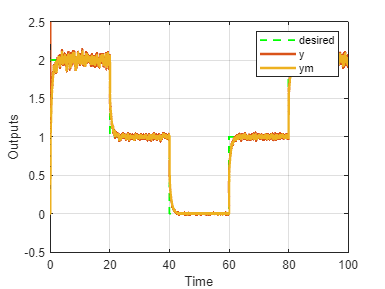

%% plot Outpots
figure;
plot(t, yd, '--g', 'LineWidth', 1.5)
hold on, grid on
plot(t, y, 'LineWidth', 2)
hold on, 
plot(t, ym, 'LineWidth', 2)
xlabel('Time'), ylabel('Outputs')
legend('desired', 'y', 'ym')

% axis([0 10 -5 5])

% figure;
% plot(t, Kp, 'LineWidth', 2)
% hold on
% plot(t, Ki, 'LineWidth', 2)
% hold on
% plot(t, Kd, 'g', 'LineWidth', 2)
% xlabel('Time'), ylabel('Amp')
% title('PID Gain Tuning')
% legend('K_p', 'K_i', 'K_d')

% Print all PID gains
fprintf('All PID Gains:\n');

All PID Gains:


for k = 1:N+1
    fprintf('Iteration: %d, Kp: %.2f, Ki: %.2f, Kd: %.2f\n', k, Kp(k), Ki(k), Kd(k));
end

Iteration: 1, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 2, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 3, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 4, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 5, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 6, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 7, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 8, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 9, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 10, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 11, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 12, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 13, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 14, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 15, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 16, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 17, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 18, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 19, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 20, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 21, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 22, Kp: 1.00, Ki: 3.00, Kd: 0.00
Iteration: 23, Kp: 1.00, Ki: 3.00, Kd: 0.


% Print final PID gains
fprintf('Final PID Gains:\n');

Final PID Gains:


fprintf('Kp: %.2f\n', Kp(end));

Kp: 1.00


fprintf('Ki: %.2f\n', Ki(end));

Ki: 3.00


fprintf('Kd: %.2f\n', Kd(end));

Kd: 0.00


After the loop, the code plots the desired output (yd), the actual output (y), and the predicted output (ym) over time.

Finally, prints the PID gains for each iteration and the final PID gains.

% Functions

function [ym, Phi] = f_hat(history_vector, W1, W2)

    X   = history_vector; % Inputs must be a n*1 vector
    N   = length(W2) - 1;
    phi = zeros(N,1);
    for i=1:N
        phi(i) = 1/(1+exp(-X.'*W1(:,i)));
    end
    Phi = [phi; 1];
    ym  = W2.'*Phi;       % W2 must be a (N+1)*1 vector because of bias
    
end

function out = betta(k)
    global beta0 T
    b = 1;
    out = beta0*exp(-b*k*T);
end

function Out = NonLinDynamic(x,u)
    
    global T
    Da = 0.72;
    B = 8;
    gama = 20;
    beta = 0.3;
    
    x1 = x(1);
    x2 = x(2);

    x1_prime = x1+T*(-x1 + Da*(1-x1)*exp(x2/(1+x2/gama)));
    
    x2_prime = x2+T*(-x2 + B*Da*(1-x1)*exp(x2/(1+x2/gama))) + beta*(u-x2);

    Out        = [x1_prime;x2_prime];
    
end

`f_hat(history_vector, W1, W2)`: This function takes three inputs: `history_vector`, `W1`, and `W2`. It calculates the output `ym` and the matrix `Phi` based on the provided inputs. Here's a step-by-step breakdown of the function:

- `X = history_vector`: Assigns the `history_vector` input to the variable `X`.

- `N = length(W2) - 1`: Calculates the length of `W2` and subtracts 1, assigning the result to `N`.

- `phi = zeros(N,1)`: Creates a column vector of zeros with dimensions N-by-1 and assigns it to the variable `phi`.

- `for i=1:N`: Iterates from 1 to N.

- `phi(i) = 1/(1+exp(-X.'*W1(:,i)))`: Calculates the value of the i-th element of `phi` based on the dot product of `X` and the i-th column of `W1`.

- `Phi = [phi; 1]`: Concatenates the `phi` vector with a 1 at the end, creating a new vector `Phi`.

- `ym = W2.'*Phi`: Calculates the output `ym` by taking the dot product of the transpose of `W2` and `Phi`.

- The function returns `ym` and `Phi` as output.

`betta(k)`: This function takes a single input `k` and calculates the output based on the global variables `beta0` and `T`. Here's how the function works:

- `global beta0 T`: Accesses the global variables `beta0` and `T`.

- `b = 1`: Assigns the value 1 to the variable `b`.

- `out = beta0*exp(-b*k*T)`: Calculates the output `out` by multiplying `beta0` with the exponential of `-b*k*T`.

- The function returns `out` as output.

`NonLinDynamic(x,u)`: This function takes two inputs: `x` and `u`. It calculates and returns the output `Out` based on the provided inputs and some global variables. Here's how the function works:

- `global T`: Accesses the global variable `T`.

- Assigns specific values to the variables `Da`, `B`, `gama`, and `beta`.

- Extracts the elements of `x` and assigns them to `x1` and `x2` variables.

- Calculates the derivatives of `x1` and `x2` based on the given equations using the provided values and inputs.

- `Out = [x1_prime;x2_prime]`: Combines the calculated derivatives of `x1` and `x2` into a column vector `Out`.

- The function returns `Out` as output.